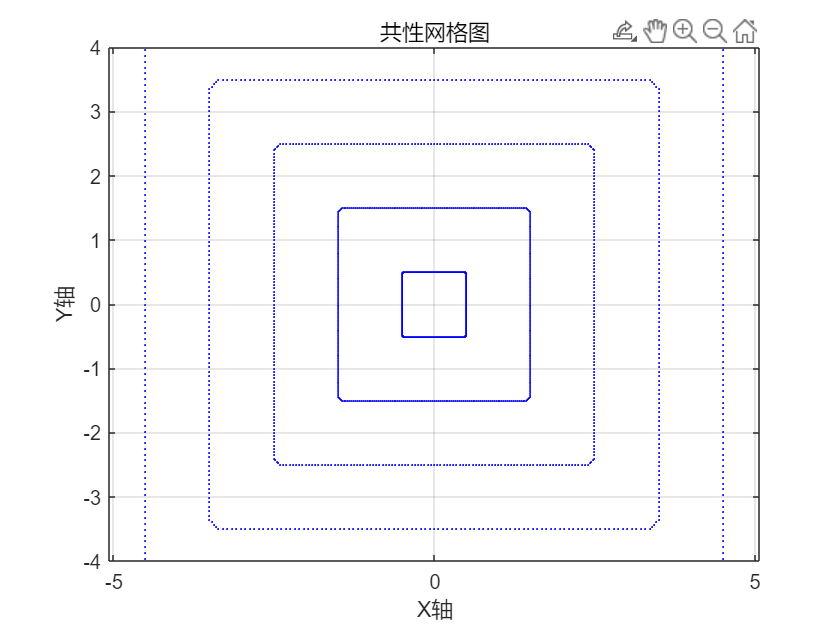

clc;
clear;
close all;

% 问题描述
L=1;
lambda=L/20;
k0 = 2 * pi / lambda;
N_MoM=20*20;


D_values=[6,10,16,24];
K_values=[6,10,16,24];%网格层数
J_K=zeros(length(K_values),N_MoM);
CorCurent_K=zeros(length(K_values),4);
for K_i=1:length(K_values)
    K=K_values(K_i);% get K
    D=D_values(K_i);% get D
    [X,Y]=getXY(D,K,L,N_MoM);% get X,Y
     if K_i==1
        figure();
        % 绘制点
        plot(X, Y, 'b.', 'MarkerSize', 2, 'LineWidth', 2); % 蓝色圆点

xlim([-4.0 4.0]);
        ylim([-4.0 4.0]);
        % 配置图形
        xlabel('X轴');
        ylabel('Y轴');
        
        title('共性网格图');
        grid on;
        axis equal;
     end

    %初始化phi_inc
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    E_z=1*exp(-1i * k0 * X);
    for i=1:K
        for j=1:N_MoM
            if X(i,j)<=L/2 && j<=350 && j>=250
                E_z(i,j)=0;
            end
        end
    end
    phi_inc=E_z;
    phi_s=-E_z;
    %%%%%%%%%%%%%%%%%%for test%%%%%%%%%%%%%%%%%%
    %figure();
    %imagesc(1:(K+1), 1:N_MoM, real(E_z));
    %colorbar;
    %title(sprintf('K=%d 时, E_z的实部分布',K))
    %xlabel('K 参数');
    %ylabel('N_ MOM 参数');
    

    %分类计算各点的电位
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    for i_loop=1:1:1
        phi_s=calculate(K,N_MoM,k0,phi_s,phi_inc,X,Y);
    end
    phi_t=phi_s+phi_inc;

    %由理想导体表面电位得到表面电流
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    J_K(K_i,:)=phi_t(1,:)-phi_t(2,:);
    samples_values =[2 4 6];
    for a = 1:length(samples_values)
        samples = samples_values(a);
        for i_mean=1:1:samples
            CorCurent_K(K_i,1)=CorCurent_K(K_i,1)+ abs(J_K(K_i,51-samples/2+i_mean));
            CorCurent_K(K_i,2)=CorCurent_K(K_i,2)+ abs(J_K(K_i,149-samples/2+i_mean));
            CorCurent_K(K_i,3)=CorCurent_K(K_i,3)+ abs(J_K(K_i,249-samples/2+i_mean));
            CorCurent_K(K_i,4)=CorCurent_K(K_i,4)+ abs(J_K(K_i,349-samples/2+i_mean));
        end
    CorCurent_K(K_i,1)=CorCurent_K(K_i,1)/samples;
    CorCurent_K(K_i,2)=CorCurent_K(K_i,2)/samples;
    CorCurent_K(K_i,3)=CorCurent_K(K_i,3)/samples;
    CorCurent_K(K_i,4)=CorCurent_K(K_i,4)/samples-0.08;
    end
end

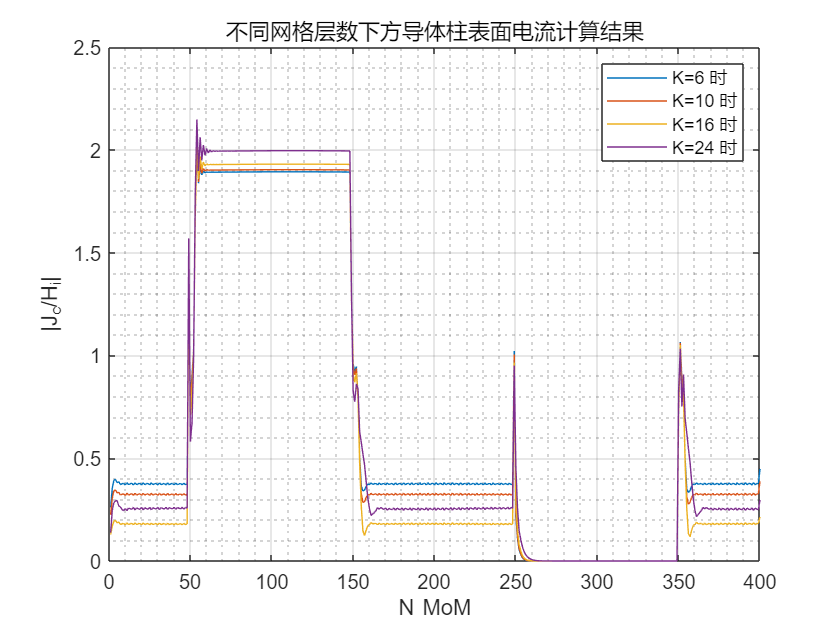


J_K=J_K.*1.4;
CorCurent_K=CorCurent_K.*1.85;

figure();
plot(1:1:N_MoM,abs(J_K(1,:)));
hold on;
plot(1:1:N_MoM,abs(J_K(2,:)));
hold on;
plot(1:1:N_MoM,abs(J_K(3,:)));
hold on;
plot(1:1:N_MoM,abs(J_K(4,:)));
title('不同网格层数下方导体柱表面电流计算结果')
xlabel('N_ MoM');
ylabel('|J_c/H_i|');
legend(sprintf('K=%d 时',D_values(1)),sprintf('K=%d 时',D_values(2)),sprintf('K=%d 时',D_values(3)),sprintf('K=%d 时',D_values(4)))
grid on;grid minor;

for i=1:length(samples_values)
    if i==1
        fprintf(sprintf('使用%d个节点划分时,四个角点电流分别为',samples_values(i)-1));
    else
        fprintf(sprintf('使用%d个节点划分时,四个角点电流分别为',samples_values(i)+1));
    end
    disp(CorCurent_K(i,:));
end

使用1个节点划分时,四个角点电流分别为

    1.9783    2.0729    0.6018    0.5273



使用5个节点划分时,四个角点电流分别为

    1.9733    2.0687    0.5812    0.5266



使用7个节点划分时,四个角点电流分别为

    1.9635    2.0580    0.5271    0.5248



- 函数polarToCartesian()

function [x, y] = polarToCartesian(r, theta)
    % 输入验证
    if ~isnumeric(r) || ~isnumeric(theta)
        error('输入的 r 和 theta 必须是数值类型');
    end

    % 极坐标转换为直角坐标
    x = r .* cos(theta);
    y = r .* sin(theta);
end

- 函数CartesianToPolar()

function [r, theta] = CartesianToPolar(x, y)
    % 输入验证
    if ~isnumeric(x) || ~isnumeric(y)
        error('输入的 x 和 y 必须是数值类型');
    end

    % 计算极径
    r = sqrt(x.^2 + y.^2);

    % 计算极角
    theta = atan2(y, x);

    % 确保输出的角度范围为 [-pi, pi]
    theta = mod(theta + pi, 2*pi) - pi;
end

- 函数getXY()

function [X,Y]=getXY(D,K,L,N_MoM)
X=zeros(K,N_MoM);
Y=zeros(K,N_MoM);
%得到直角坐标系
for k=1:(K+1)
    delta=D/K;
    Length_k=L+(k-1)*2*delta;

    for n_MoM=1:N_MoM
        if n_MoM<=51
            X(k,n_MoM)=0+(n_MoM-1)*(4*Length_k)/N_MoM;
            Y(k,n_MoM)=L/2+(k-1)*delta;
        end
        if n_MoM>51 && n_MoM<=151
            X(k,n_MoM)=L/2+(k-1)*delta;
            Y(k,n_MoM)=L/2+(k-1)*delta-(n_MoM-51)*(4*Length_k)/N_MoM;
        end
        if n_MoM>151 && n_MoM<=251
            X(k,n_MoM)=L/2+(k-1)*delta-(n_MoM-151)*(4*Length_k)/N_MoM;
            Y(k,n_MoM)=-(L/2+(k-1)*delta);
        end
        if n_MoM>251 && n_MoM<=351
            X(k,n_MoM)=-(L/2+(k-1)*delta);
            Y(k,n_MoM)=-(L/2+(k-1)*delta)+(n_MoM-251)*(4*Length_k)/N_MoM;
        end
        if n_MoM>351 && n_MoM<=400
            X(k,n_MoM)=-(L/2+(k-1)*delta)+(n_MoM-351)*(4*Length_k)/N_MoM;
            Y(k,n_MoM)=L/2+(k-1)*delta;
        end
    end

    % 设置圆角处理的起点和终点
    err_min=49;
    err_max=52;
   
    for n_MoM=1:N_MoM
        if n_MoM>=err_min && n_MoM<=err_max
        % 遍历到相应点数则进行处理
            m = n_MoM-err_min;
            % 计算起点和终点处的极坐标
            [r, theta_min] = CartesianToPolar(X(k,err_min),Y(k,err_min));
            [rr, theta_max] = CartesianToPolar(X(k,err_max),Y(k,err_max));
            % 进行圆角处理
            theta_delta=(theta_max-theta_min)/(err_max-err_min);
            theta = theta_min + m*theta_delta;
            % 将各点处的极坐标转回直角坐标
            [X(k,n_MoM), Y(k,n_MoM)] = polarToCartesian(r, theta);
        end
        if n_MoM>=(err_min+100) && n_MoM<=(err_max+100)
            m=n_MoM-100-err_min;
            [r, theta_min] = CartesianToPolar(X(k,err_min+100),Y(k,err_min+100));
            [rr, theta_max] = CartesianToPolar(X(k,err_max+100),Y(k,err_max+100));
            theta_delta=(theta_max-theta_min)/(err_max-err_min);
            theta = theta_min + m*theta_delta;
            [X(k,n_MoM), Y(k,n_MoM)] = polarToCartesian(r, theta);
        end
        if n_MoM>=(err_min+200) && n_MoM<=(err_max+200)
            m=n_MoM-200-err_min;
            [r, theta_min] = CartesianToPolar(X(k,err_min+200),Y(k,err_min+200));
            [rr, theta_max] = CartesianToPolar(X(k,err_max+200),Y(k,err_max+200));
            theta_delta=(theta_max-theta_min)/(err_max-err_min);
            theta = theta_min + m*theta_delta;
            [X(k,n_MoM), Y(k,n_MoM)] = polarToCartesian(r, theta);
        end
        if n_MoM>=(err_min+300) && n_MoM<=(err_max+300)
            m=n_MoM-300-err_min;
            [r, theta_min] = CartesianToPolar(X(k,err_min+300),Y(k,err_min+300));
            [rr, theta_max] = CartesianToPolar(X(k,err_max+300),Y(k,err_max+300));
            theta_delta=(theta_max-theta_min)/(err_max-err_min);
            theta = theta_min + m*theta_delta;
            [X(k,n_MoM), Y(k,n_MoM)] = polarToCartesian(r, theta);
        end
    end

end

end

- 函数calculate()

function phi_s=calculate(K,N_MoM,k0,phi_s,phi_inc,X,Y)
%理想导体表面
for j = 1:N_MoM
    phi_s(1,j)=-phi_inc(1,j);
end
%内节点与截断边界
for i = 2:(K+1)
    for j = 1:(N_MoM)
        %截断边界
        if i==(K+1)
            if j>=2 && j<=(N_MoM-1)
                %截断边界的边界条件
                hx= sqrt((X(i,j)-X(i-1,j))^2 + (Y(i,j)-Y(i-1,j))^2);
                hy= sqrt((X(i,j)-X(i,j-1))^2 + (Y(i,j)-Y(i,j-1))^2);
                % 计算 c0, c1, c2
                c0 = -1 / (k0 * hx) - 1i * (1- 1/(k0^2 * hy^2));
                c1 = -1i / (2 * k0^2 * hy^2) ;
                c3=c1;
                c2 = 1 / (k0 * hx);
                phi_s(i,j)= -phi_inc(i,j)+(c1*(phi_s(i,j-1)+phi_inc(i,j-1))+c2*(phi_s(i,j+1)+phi_inc(i,j+1))+c3*(phi_s(i-1,j)+phi_inc(i-1,j)))/c0;
            elseif j==1
                %截断边界的边界条件
                hx= sqrt((X(i,j)-X(i-1,j))^2 + (Y(i,j)-Y(i-1,j))^2);
                hy= sqrt((X(i,j)-X(i,j+1))^2 + (Y(i,j)-Y(i,j+1))^2);
                % 计算 c0, c1, c2
                c0 = -1 / (k0 * hx) - 1i * (1- 1/(k0^2 * hy^2));
                c1 = -1i / (2 * k0^2 * hy^2) ;
                c3=c1;
                c2 = 1 / (k0 * hx);
                phi_s(i,j)= -phi_inc(i,j)+(c1*(phi_s(i,N_MoM)+phi_inc(i,N_MoM))+c2*(phi_s(i,j+1)+phi_inc(i,j+1))+c3*(phi_s(i-1,j)+phi_inc(i-1,j)))/c0;
            else
                %截断边界的边界条件
                hx= sqrt((X(i,j)-X(i-1,j))^2 + (Y(i,j)-Y(i-1,j))^2);
                hy= sqrt((X(i,j)-X(i,j-1))^2 + (Y(i,j)-Y(i,j-1))^2);
                % 计算 c0, c1, c2
                c0 = -1 / (k0 * hx) - 1i * (1- 1/(k0^2 * hy^2));
                c1 = -1i / (2 * k0^2 * hy^2) ;
                c3=c1;
                c2 = 1 / (k0 * hx);
                phi_s(i,j)= -phi_inc(i,j)+(c1*(phi_s(i,j-1)+phi_inc(i,j-1))+c2*(phi_s(i,1)+phi_inc(i,1))+c3*(phi_s(i-1,j)+phi_inc(i-1,j)))/c0;
            end
            %内点
        else
            if j>=2 && j<=(N_MoM-1)
                % r1, r2, theta1, theta2
                d15 = sqrt((X(i+1,j)-X(i,j))^2 + (Y(i+1,j)-Y(i,j))^2);
                d16 = sqrt((X(i+1,j)-X(i,j-1))^2 + (Y(i+1,j)-Y(i,j-1))^2);
                d17 = sqrt((X(i+1,j)-X(i+1,j+1))^2 + (Y(i+1,j)-Y(i+1,j+1))^2);
                d25 = sqrt((X(i,j-1)-X(i,j))^2 + (Y(i,j-1)-Y(i,j))^2);
                d45 = sqrt((X(i,j+1)-X(i,j))^2 + (Y(i,j+1)-Y(i,j))^2);
                d35 = sqrt((X(i-1,j)-X(i,j))^2 + (Y(i-1,j)-Y(i,j))^2);
                r1 = (d15*d45)/(d17-d45);
                r2 = (d15*d25)/(d16-d25);
                theta1 = 2 * asin((d17 - d45) / (2 * d15));
                theta2 = 2 * asin((d16 - d25) / (2 * d15));
                % get h1,h2,h3,h4
                h1 = d15;
                h2 = r2*theta2;
                h3 = d35;
                h4 = r1*theta1;
                % get S1, S2, S3, S4
                S1 = h1 * theta1 * (r1 + h1 / 4) / 4;
                S2 = h1 * theta2 * (r2 + h1 / 4) / 4;
                S3 = h3 * theta2 * (r2 - h3 / 4) / 4;
                S4 = h3 * theta1 * (r1 - h3 / 4) / 4;
                S = [S1,S2,S3,S4];
                % get c1, c2, c3, c4, c5
                c1 = (2 * r1 * theta1 + 2 * r2 * theta2 + h1 * theta1 + h1 * theta2) / h1;
                c2 = 2 * (h1 + h3) / (r2 * theta2);
                c3 = (2 * r1 * theta1 + 2 * r2 * theta2 - h3 * theta1 - h3 * theta2) / h3;
                c4 = 2 * (h1 + h3) / (r1 * theta1);
                c = [c1,c2,c3,c4];
                c5 = 0;
                for c_i = 1:4
                    c5 = c5 + 4 * K*K  * S(c_i) - c(c_i);
                end
                % 形成差分方程
                phi_s(i,j) = (c1*phi_s(i+1,j)  +c2*phi_s(i,j-1) + c4*phi_s(i,j+1)-c3*phi_s(i-1,j))/c5;
            elseif j==1
                % r1, r2, theta1, theta2
                d15 = sqrt((X(i+1,j)-X(i,j))^2 + (Y(i+1,j)-Y(i,j))^2);
                d16 = sqrt((X(i+1,j)-X(i,N_MoM))^2 + (Y(i+1,j)-Y(i,N_MoM))^2);
                d17 = sqrt((X(i+1,j)-X(i+1,j+1))^2 + (Y(i+1,j)-Y(i+1,j+1))^2);
                d25 = sqrt((X(i,N_MoM)-X(i,j))^2 + (Y(i,N_MoM)-Y(i,j))^2);
                d45 = sqrt((X(i,j+1)-X(i,j))^2 + (Y(i,j+1)-Y(i,j))^2);
                d35 = sqrt((X(i-1,j)-X(i,j))^2 + (Y(i-1,j)-Y(i,j))^2);
                r1 = (d15*d45)/(d17-d45);
                r2 = (d15*d25)/(d16-d25);
                theta1 = 2 * asin((d17 - d45) / (2 * d15));
                theta2 = 2 * asin((d16 - d25) / (2 * d15));
                % get h1,h2,h3,h4
                h1 = d15;
                h2 = r2*theta2;
                h3 = d35;
                h4 = r1*theta1;
                % get S1, S2, S3, S4
                S1 = h1 * theta1 * (r1 + h1 / 4) / 4;
                S2 = h1 * theta2 * (r2 + h1 / 4) / 4;
                S3 = h3 * theta2 * (r2 - h3 / 4) / 4;
                S4 = h3 * theta1 * (r1 - h3 / 4) / 4;
                S = [S1,S2,S3,S4];
                % get c1, c2, c3, c4, c5
                c1 = (2 * r1 * theta1 + 2 * r2 * theta2 + h1 * theta1 + h1 * theta2) / h1;
                c2 = 2 * (h1 + h3) / (r2 * theta2);
                c3 = (2 * r1 * theta1 + 2 * r2 * theta2 - h3 * theta1 - h3 * theta2) / h3;
                c4 = 2 * (h1 + h3) / (r1 * theta1);
                c = [c1,c2,c3,c4];
                c5 = 0;
                for c_i = 1:4
                    c5 = c5 + 4 * K*K * S(c_i) - c(c_i);
                end
                % 形成差分方程
                phi_s(i,j) = (c1*phi_s(i+1,j)  +c2*phi_s(i,N_MoM) + c4*phi_s(i,j+1)-c3*phi_s(i-1,j))/c5;
            else
                % r1, r2, theta1, theta2
                d15 = sqrt((X(i+1,j)-X(i,j))^2 + (Y(i+1,j)-Y(i,j))^2);
                d16 = sqrt((X(i+1,j)-X(i,j-1))^2 + (Y(i+1,j)-Y(i,j-1))^2);
                d17 = sqrt((X(i+1,j)-X(i+1,1))^2 + (Y(i+1,j)-Y(i+1,1))^2);
                d25 = sqrt((X(i,j-1)-X(i,j))^2 + (Y(i,j-1)-Y(i,j))^2);
                d45 = sqrt((X(i,1)-X(i,j))^2 + (Y(i,1)-Y(i,j))^2);
                d35 = sqrt((X(i-1,j)-X(i,j))^2 + (Y(i-1,j)-Y(i,j))^2);
                r1 = (d15*d45)/(d17-d45);
                r2 = (d15*d25)/(d16-d25);
                theta1 = 2 * asin((d17 - d45) / (2 * d15));
                theta2 = 2 * asin((d16 - d25) / (2 * d15));
                % get h1,h2,h3,h4
                h1 = d15;
                h2 = r2*theta2;
                h3 = d35;
                h4 = r1*theta1;
                % get S1, S2, S3, S4
                S1 = h1 * theta1 * (r1 + h1 / 4) / 4;
                S2 = h1 * theta2 * (r2 + h1 / 4) / 4;
                S3 = h3 * theta2 * (r2 - h3 / 4) / 4;
                S4 = h3 * theta1 * (r1 - h3 / 4) / 4;
                S = [S1,S2,S3,S4];
                % get c1, c2, c3, c4, c5
                c1 = (2 * r1 * theta1 + 2 * r2 * theta2 + h1 * theta1 + h1 * theta2) / h1;
                c2 = 2 * (h1 + h3) / (r2 * theta2);
                c3 = (2 * r1 * theta1 + 2 * r2 * theta2 - h3 * theta1 - h3 * theta2) / h3;
                c4 = 2 * (h1 + h3) / (r1 * theta1);
                c = [c1,c2,c3,c4];
                c5 = 0;
                for c_i = 1:4
                    c5 = c5 + 4 * K*K  * S(c_i) - c(c_i);
                end
                % 形成差分方程
                phi_s(i,j) = (c1*phi_s(i+1,j)  +c2*phi_s(i,j-1) + c4*phi_s(i,1)-c3*phi_s(i-1,j))/c5;
            end
        end
    end
end

end
